# Modelación Computacional de Sistemas Eléctromagneticos 

**(Gpo 13)**

Instituto Tecnológico y De Estudios Superiores de Monterrey

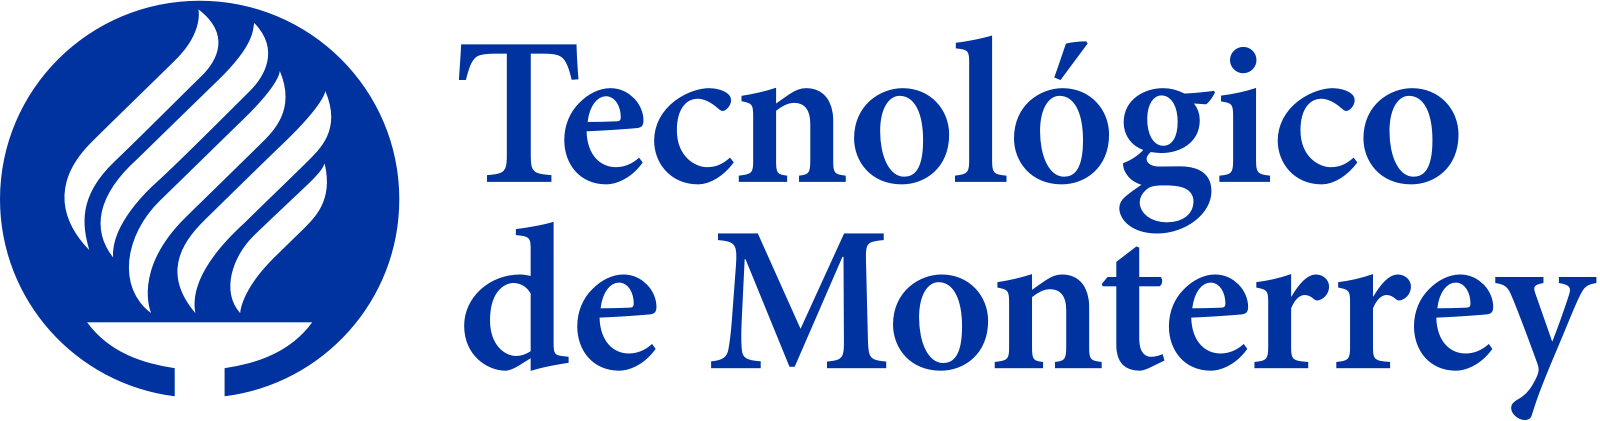

Lidia Paola Díaz Ramírez **A01369117**

Yusdivia Molina Román **A01653120**

Johan Donato Cabrera Martínez **A01657922**

Eduardo González Luna **A01658281**

Alejandro Hernández De la Torre **A01651516**

**Equipo 1 **

**Entrega Final**

11/06/2020

#### Contexto

La Ley de Faraday nos explica que en el campo magnético el flujo a través de una superficie cambia, aparece la fuerza electromotriz inducida, lo cual hace que también exista una inducción electromagnética. La fuerza electromotriz junto con la corriente inducida se oponen a la causa que las produce, esto da paso a la llamada Ley de Lenz.

Si m es la masa del imán que cae, entonces su movimiento, debido a su peso mg y la fuerza de frenado magnético F, viene dada por la segunda ley de Newton como:

La solución a esta ecuación diferencial después de la separación de las variables z y t da la velocidad variable z(t) del imán que cae dentro del tubo. Como en muchos casos de movimiento de un cuerpo, bajo la acción combinada de una fuerza de retardo y una fuerza constante, el movimiento del imán consiste en un régimen transitorio inicial de corta duración seguido de un movimiento terminal uniforme, donde la velocidad constante es precisamente la velocidad terminal

#### Descripción del Entregable

En este entregable se busca hacer una simulación en formato app para una mejor experiencia del usuario en este caso haciendo un frenado magnetico para un parque de atracciones, el usuario podra manipular valores como la masa, velocidad inicial, Espesor, Mu (μ), Radio, P material, tiempo final, numero de intervalos e incluso se coloco una lampara en donde marca cuando la aceleración es muy peligrosa esto pensando en la seguridad, como en anteriores entregables este generara 3 graficas 

- Distancia contra tiempo

- Velocidad contra tiempo

- Aceleracion contra tiempo

Los valores de los intervalos que se presnetan son los que tienen como objetivo modelar un experimento a escala. Los valores se estimaron con base en ejercicios del tema, o de temáticas que utilizamos para la elaboración del proyecto; como de la página "sc.ehu", en un ejercicio sobre un imán (ver referencias). Asimismo nos basamos en materiales audiovisuales (ver referencias) donde se reproduce el experimento. 

#### Programación

%% Runge Kutta 4 orden ecuacion 1 orden
clc;clear;
m=0.1;% Masa del imán en kg
g=9.81;%Valor de la gravedad
E=5e-3;% Espesor del tubo 
M=5;%Momento del imán 
a=0.02;% Radio del tubo 
P=1.7e-8;% Resistividad el material, en este caso del cobre
k=6.94e-14*(E*M^2)/(a^4*P);%Constante

f= @(t,v) g-(k/m)*v;%Fórmula obtenida por el diagrama de cuerpo libre
x0= 0;%Posición inicial
y0=0;%Velocidad inicial 
h=0.079;
tSim=1;%Tiempo que se evaluará el movimiento en segundos

    N=ceil((tSim-x0)/h); 
    %Se crean los vectores a llenar con cada iteración
    x_e=zeros(1,N+1);
    y_e=zeros(1,N+1);
    %Se establecen los primeros valores de los vectores anteriores
    x_e(1) = x0; 
    y_e(1) = y0; 
    %Se hace un ciclo de 1 hasta los pasos que se deban seguir, están
    %dictaminados por el límite, x0 y h
    for i=1:N
        x_e(i+1)= x_e(i)+h;
        k1= f(x_e(i),y_e(i));
        k2= f(x_e(i)+1/2*h,y_e(i)+1/2*k1*h);
        k3= f(x_e(i)+1/2*h, y_e(i)+1/2*k2*h);
        k4= f(x_e(i)+h,y_e(i)+k3*h);
        y_e(i+1)= y_e(i)+1/6*(k1+2*k2+2*k3+k4)*h;
        %Se van llenando los espacios de x_e y y_e
        
    end
 
    tiledlayout(2,2)
    %Se hace un vector vacío para calcular la distancia 
    dd= zeros(1,N+1);
    %Con el ciclo se llena las distancias e
for k =2:N+1
    dd(k)= (dd(k-1)+y_e(k));
end
nexttile
plot(x_e,dd)
title("Distancia contra tiempo");
xlabel("Tiempo en segundos");
ylabel("Distancia en m ");

    
nexttile
plot(x_e, y_e)
title("Velocidad contra tiempo");
xlabel("Tiempo en segundos");
ylabel("Velocidad en m/s ");
velocidadAprox=max(y_e);

aa= zeros(1,N+1);
%Cálculo de la aceleración por diferencia de velocidad entre el diferencial
%de tiempo
for j =1:N
    aa(j)= (y_e(j+1)-y_e(j))/h;
end
nexttile
plot(x_e,aa)
title("Aceleración contra tiempo");
xlabel("Tiempo en segundos");
ylabel("Aceleración en m/s^2 ");

    

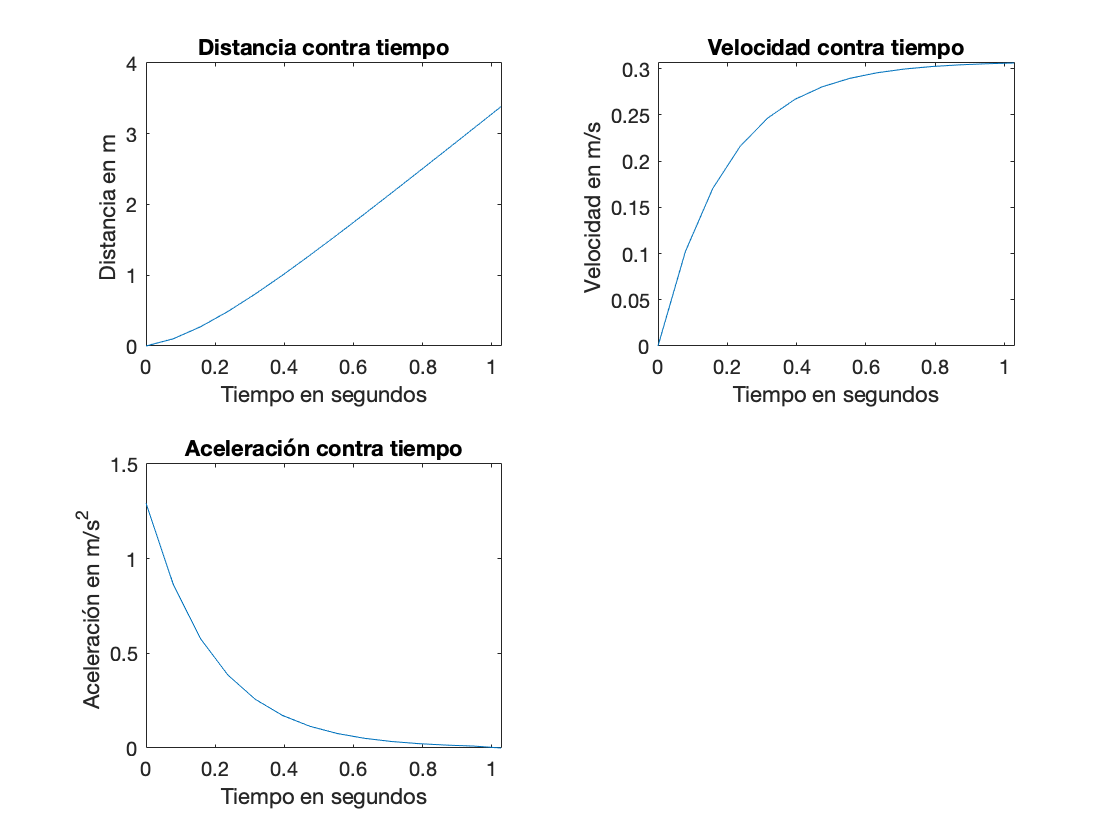

%% ecuación 2 orden

syms z(t);

intervalos=100;

k=6.94e-14*(E*M^2)/(a^4*P);

y0=0;% Posición inicial en m
v0=0;% Velocidad inicial en m/s
r1= diff(z,t,2)==g-((k*diff(z,t))/m); %Se introduce la ecuación que corresponde al modelo físico
[V]= odeToVectorField(r1); %Se convierte esta ecuación diferencial de 2 orden en un sistema de primer orden
M= matlabFunction(V, 'vars', {'t','Y'});%La expresión V se transforma en una función con "vars" para definir los argumentos de entrada

sol = ode45(M,[0 tSim],[y0 v0]);%Se guardan ambas ecuaciones que describen el movimiento en esa variable
x = linspace(0,tSim,(tSim*200)+1);%Crea un vector desde 0 hasta un valor que depende del tiempo en que se evaluará el movimiento
[tt,yy]= ode45(M, [0 tSim], [y0 v0]);%Se guardan en 2 variables la solución numérica
% El primer paréntesis coresponde al tiempo donde será evaluado el movimiento
% El segundo paréntesis define los valores iniciales de la distancia y velocidad inicial
tiledlayout(2,2)%Para poder poner más de 1 gráfica en el mismo espacio

nexttile%Define que esta será la primera gráfica en mostrarse 
plot(tt,yy(1:length(tt),1), '--r');% Se grafica la distancia, solo al poner el vector de la primera columna de "yy"
title("Distancia contra tiempo");% Etiquetas para la gráfica 
xlabel("Tiempo en seg");
ylabel("Distancia en m ");

nexttile%Indica la siguinete gráfica a poner
plot(tt,yy( 1:length(tt),2),'--r');%Se toma la segunda columna que corresponde a los valores de la velocidad y los grafica contra "tt"
veloci = deval(sol,x,2);
title("Velocidad contra tiempo");% Etiquetas para la gráfica 
xlabel("Tiempo en seg");
ylabel("Velocidad en m/s ");

N=length(x);%Define N como el mismo número a la longitud de los intervalos de tiempo 
aa= zeros(N,1);% Se hace un vector vacío de la misma longitud que "tt"
for j =2:N%Se hace un ciclo para llenar los valores del vector vacío anterior 
    aa(j)= (veloci(j)-veloci(j-1))/(tSim/N);% Se saca la diferencia de la velocidad y se divide entre los intervalos de tiempo
    %Los intervalos de tiempo se definen por el tiempo máximo entre el número de intervalos hechos (N)
end
nexttile%Se utiliza para indicar la siguiente gráfica a poner, que es la de la aceleración 
plot(x,aa,'--r');% Se grafica el tiempo contra la aceleración
title("Aceleración contra tiempo");% Etiquetas para la gráfica 
xlabel("Tiempo en seg");
ylabel("Aceleración en m/s^2 ");

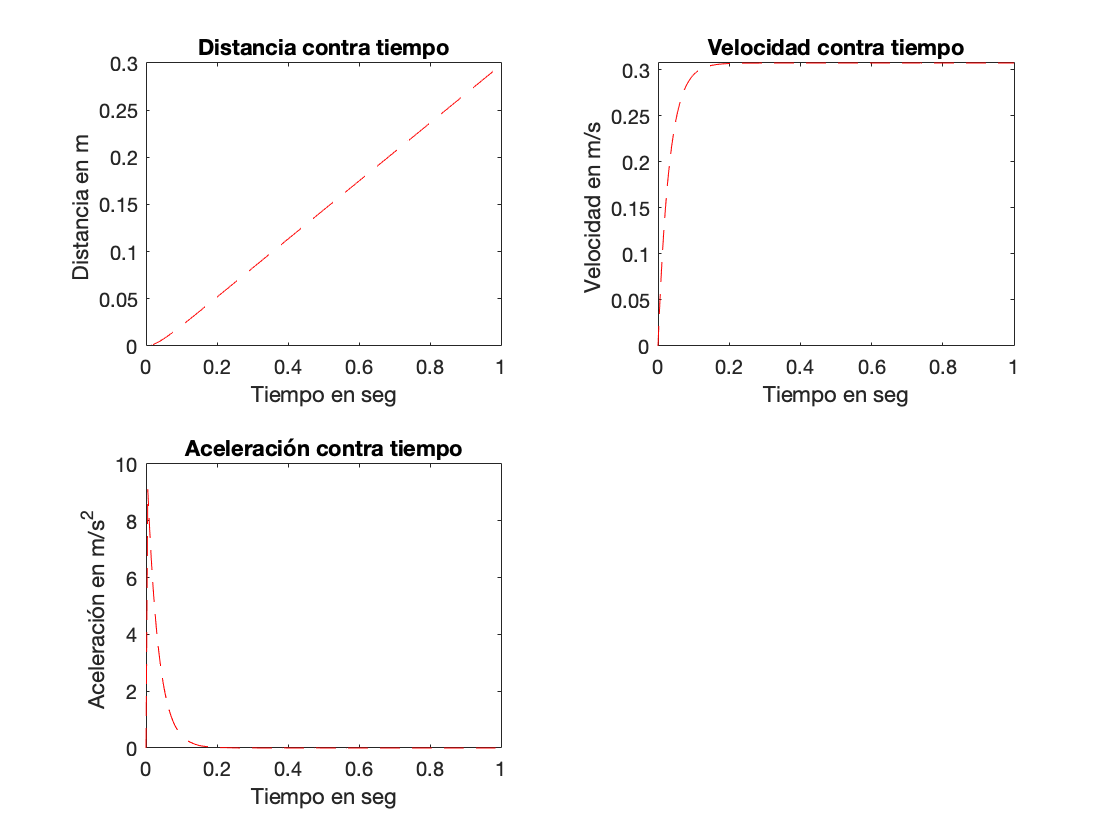

%% Método analítico
%nota, se volvieron a poner los valores iniciales aquí, por un error que
%llegaba a marcar
m=0.1;
g=9.81;
E=5e-3;
M=5;
a=0.02;
P=1.7e-8;
k=6.94e-14*(E*M^2)/(a^4*P);
tSim=1;
tau=m/k;
t = linspace(0,tSim,(tSim*200)+1);
v=(m*g)/k*(1-exp(-(k*t)/m));
vt=m*g/k;
x=vt*(t-tau)+vt*tau*exp(-t/tau);

tiledlayout(2,2)

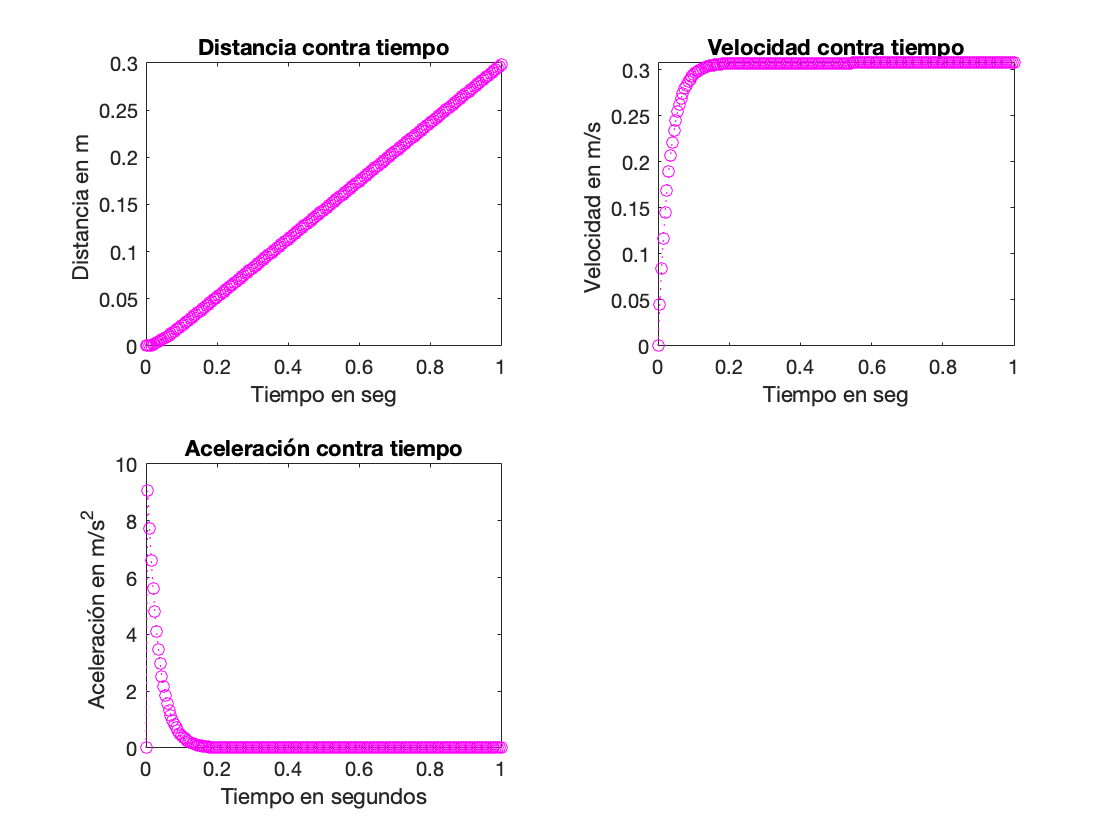


nexttile
plot(t,x,':mo');
title("Distancia contra tiempo");% Etiquetas para la gráfica 
xlabel("Tiempo en seg");
ylabel("Distancia en m ");

nexttile
plot(t,v,':mo');
title("Velocidad contra tiempo");% Etiquetas para la gráfica 
xlabel("Tiempo en seg");
ylabel("Velocidad en m/s ");
velocidadReal=max(vt);

N=length(t);
%Vector vacío para calcular la aceleración
acel= zeros(1,N);
for j =2:N
    acel(j)= (v(j)-v(j-1))/(t(j)-t(j-1));
    %Como en métodos anteriores es la diferencia de las velocidades entre
    %las diferencias de tiempo 
end
nexttile
plot(t,acel,':mo')
title("Aceleración contra tiempo");
xlabel("Tiempo en segundos");
ylabel("Aceleración en m/s^2 ");


error= (velocidadReal*1)/100;
if velocidadAprox<(velocidadReal+error) && velocidadAprox>(velocidadReal-error)
    fprintf("Valor aceptable del paso de h")
end

Valor aceptable del paso de h

Para determinar que tan bueno exacto suelen ser los métodos numéricos para la solución de ecuaciones diferenciales comparamos las velocidades terminales que nos daban como resultado. De este modo pudimos determinar el valor máximo de h del método de Runge Kutta de cuarto orden, de tal modo que se encontrara dentro de una tolerancia de 1% con respecto a la solución analítica. Para ello nos apoyamos del código anterior que nos indica cuando el valor dado por Runge Kutta está dentro de este parámetro. Tras varias pruebas determinamos que el valor máximo de h es 0.08, si ponemos valores más grandes, se pierde precisión, haciendo que los métodos no sean tan confiables. Además, que las gráficas empiezan a distorsionarse y verse más como líneas rectas unidas y no como una curva continua; por ello las gráficas dejan de modelar el frenado. Se dejó el código para que el usuario pueda cambiar los valores y vea si se cumple con el rango de error.

#### Solución de Preguntas

- Comenta cómo cambiarían tus resultados considerando que el tubo *no* es infinito y que por la tanto, la fuerza magnética depende también de la *posición *z* dentro del tubo* (además de la velocidad).

Si consideramos que ahora el tubo no es infinito, entonces habría una mayor fuerza magnética en los extremos del mismo, puesto que hay más lineas de campo en donde termina el túnel y entre más lineas de campo haya, será mas fuerte la fuerza magnetica.

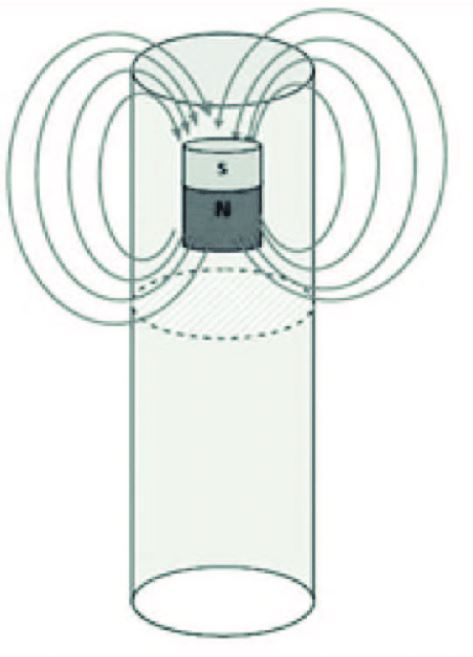 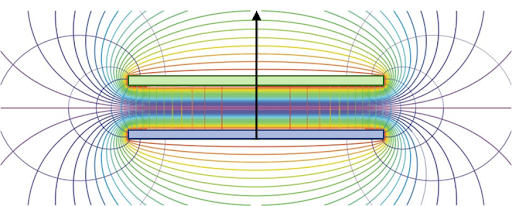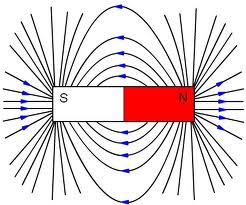

Entonces podemos decir que entre mas a los extremos se encuentre, mayor será la fuerza magnética.

#### Conclusiones

El electromagnetismo dio su origen en uno de los inventos del físico y químico Alessandro Volta, que fue la pila eléctrica en el año 1799, apartir de ese entonces el electromagnetismo ha sido de gran ayuda para los avances tecnológicos que se tienen en la actualidad. La aplicación de sus leyes ha ayudado en el desarrollo de algunos de los aparatos que utilizamos en nuestro día a día como el celular y la computadora, e incluso la generación de corriente eléctrica.

En el transcurso de este parcial aprendimos las bases del UI que son necesarias para cualquier programador en general, tambien aprendimos más a profundidad la importancia de la electricidad y el electromagnetismo. Pero estos solo son conceptos cuando los relacionamos con la realidad son cuando se vuelven importantes y nos recuerdan hacia donde vamos dirijidos y por que estamos aprendiendo. Juntando estos 2 conocimientos llegamos a una simulación de la realidad que nos puede ayudar a determinar la seguridad de las personas que es un uso de la computación, este proyecto en general fue de nuestro agrado por que podemos modelar algo interesante y darle un uso eficiente que es el objetivo de los retos.

#### Referencias

Danoso, G., Ladera , C., L., & Martín, P. (2009, 25 marzo). Recuperado 11 de junio de 2020 de http://iopscience.iop.org/0143-0807/30/4/018

Cienciabit: Ciencia y tecnología. (2019, 16 julio). Ley de Lenz. Cilindro y tubo de cobre+ imán [Archivo de vídeo]. En YouTube. Recuperado de https://www.youtube.com/watch?v=eWy9UxiveQw

Oscilaciones transversales de un imn. (s. f.). Recuperado 11 de junio de 2020, de http://www.sc.ehu.es/sbweb/fisica/elecmagnet/campo_magnetico/iman1/iman1.htm

Robledo, V & Molina, M. (2020). Entrega Final Reto_Frenado magnético, de Canva disponible en:[https://experiencia21.tec.mx/courses/32612/assignments/857490?return_to=https%3A%2F%2Fexperiencia21.tec.mx%2Fcalendar%23view_name%3Dmonth%26view_start%3D2020-06-10](https://experiencia21.tec.mx/courses/32612/assignments/857490?return_to=https%3A%2F%2Fexperiencia21.tec.mx%2Fcalendar%23view_name%3Dmonth%26view_start%3D2020-06-10)